Drop 25 ants randomly on a 1 meter rod. Each ant faces left or right with probability 50/50. Ants walk with a speed 1cm/s in the direction they are facing. Whenever two ants collide they reverse direction. When ants reach the end of the rod, they fall off. The middle ant is called Alice

a. How long until Alice to fall off?

b. Plot the position of Alice with time

## Part a

n = input('number an ODD of ants (only odd no.) : ')

n = 25

if mod(n,2)==0
    disp(['not an ood no'])
    quit
end

pos = sort(randi([1 100],1,n))   % gives random integres between 1 and 100 of 5 elements (sorted)

pos =      4    10    13    15    16    28    43    49    55    64    66    68    80    81    82    85    91    92    92    94    96    96    96    97    98


while diff(pos) ==0
    pos = sort(randi([1 100],1,n)) % itrate untill we get no ants in same opsition
end

pos_save = pos;                  % saving values to use it for part 3 of problem
alice = (length(pos)-1)/2 +1;    % always the middle element of pos
C = rand([1 n]) >.5;    % logic matrix which gives 0 and 1 for that condition
dir = double(C);        % converted logic matrix to normal
dir(dir==0) = -1;       % converted zeros to -1
dir_save = dir;         % all 1 values => positive direction and -1 => -ve direction
dt = 1;                 % time step as 1 sec
speed = ones([1 n]);    % speed with 1 cm/s
velocity =speed.*dir;   % velocity is speed with direction
dis = velocity*dt;
t=0;
alice_pos = pos(alice);     % initializing counter for alice ant position
while(pos(alice)>0)
    cross = find(diff(pos) + diff(dis) < 0); % crossing happens when relative displacement is greater than relative change in postition => avilable distance between ants is larger than next change in displacement (take care directrions)
    
    if cross                % inter change values if there is crossing, this operation is not valid thus time not counted
        dis(cross) = dis(cross)*-1;
        dis(cross+1) = dis(cross+1)*-1;
        disp(['directions of ',int2str(cross),' and ',int2str(cross+1),' are interchanged'])
        
    elseif isempty(cross)   % if there is no crossing => operation valid thus time is counted
        pos = pos + dis
        pos(pos<0 | pos>100)=NaN;
        t = t+dt
        alice_pos = [alice_pos pos(alice)];     % alice ant position counter
        
    else
        disp(['error'])
        break
    end
end

directions of 4  14 and 5  15 are interchanged


pos =      5    11    12    14    17    29    42    48    54    63    67    69    79    80    83    84    90    93    93    93    95    95    97    98    99


t = 1

directions of 2  15  19 and 3  16  20 are interchanged
directions of 18 and 19 are interchanged


pos =      6    10    13    13    18    30    41    47    53    62    68    70    78    79    82    85    89    92    94    94    94    94    98    99   100


t = 2

directions of 3  20 and 4  21 are interchanged
directions of 19  21 and 20  22 are interchanged
directions of 20 and 21 are interchanged


pos =      7     9    12    14    19    31    40    46    52    61    69    71    77    78    81    86    88    91    93    93    95    95    99   100   101


t = 3

pos =      8     8    11    15    20    32    39    45    51    60    70    72    76    77    80    87    87    90    92    92    96    96   100   101   NaN


t = 4

directions of 1  16 and 2  17 are interchanged


pos =      7     9    10    16    21    33    38    44    50    59    71    73    75    76    79    86    88    89    91    91    97    97   101   NaN   NaN


t = 5

directions of 2  17 and 3  18 are interchanged


pos =      6     8    11    17    22    34    37    43    49    58    72    74    74    75    78    85    87    90    90    90    98    98   NaN   NaN   NaN


t = 6

directions of 12  18 and 13  19 are interchanged
directions of 13  19 and 14  20 are interchanged


pos =      5     7    12    18    23    35    36    42    48    57    73    73    73    76    77    84    86    89    89    91    99    99   NaN   NaN   NaN


t = 7

directions of 6  11  14 and 7  12  15 are interchanged
directions of 12 and 13 are interchanged


pos =      4     6    13    19    24    34    37    41    47    56    72    72    74    75    78    83    85    88    88    92   100   100   NaN   NaN   NaN


t = 8

directions of 13 and 14 are interchanged


pos =      3     5    14    20    25    33    38    40    46    55    71    71    73    76    79    82    84    87    87    93   101   101   NaN   NaN   NaN


t = 9

pos =      2     4    15    21    26    32    39    39    45    54    70    70    72    77    80    81    83    86    86    94   NaN   NaN   NaN   NaN   NaN


t = 10

directions of 7  15 and 8  16 are interchanged


pos =      1     3    16    22    27    31    38    40    44    53    69    69    71    78    79    82    82    85    85    95   NaN   NaN   NaN   NaN   NaN


t = 11

directions of 14  16 and 15  17 are interchanged


pos =      0     2    17    23    28    30    37    41    43    52    68    68    70    77    80    81    83    84    84    96   NaN   NaN   NaN   NaN   NaN


t = 12

directions of 15  17 and 16  18 are interchanged
directions of 18 and 19 are interchanged


pos =     -1     1    18    24    29    29    36    42    42    51    67    67    69    76    79    82    82    83    85    97   NaN   NaN   NaN   NaN   NaN


t = 13

directions of 5   8  16 and 6   9  17 are interchanged
directions of 17 and 18 are interchanged


pos =    NaN     0    19    25    28    30    35    41    43    50    66    66    68    75    78    81    81    84    86    98   NaN   NaN   NaN   NaN   NaN


t = 14

pos =    NaN    -1    20    26    27    31    34    40    44    49    65    65    67    74    77    80    80    85    87    99   NaN   NaN   NaN   NaN   NaN


t = 15

directions of 4 and 5 are interchanged


pos =    NaN   NaN    21    25    28    32    33    39    45    48    64    64    66    73    76    79    79    86    88   100   NaN   NaN   NaN   NaN   NaN


t = 16

directions of 6 and 7 are interchanged


pos =    NaN   NaN    22    24    29    31    34    38    46    47    63    63    65    72    75    78    78    87    89   101   NaN   NaN   NaN   NaN   NaN


t = 17

directions of 9 and 10 are interchanged


pos =    NaN   NaN    23    23    30    30    35    37    45    48    62    62    64    71    74    77    77    88    90   NaN   NaN   NaN   NaN   NaN   NaN


t = 18

directions of 3  5 and 4  6 are interchanged


pos =    NaN   NaN    22    24    29    31    36    36    44    49    61    61    63    70    73    76    76    89    91   NaN   NaN   NaN   NaN   NaN   NaN


t = 19

directions of 7 and 8 are interchanged


pos =    NaN   NaN    21    25    28    32    35    37    43    50    60    60    62    69    72    75    75    90    92   NaN   NaN   NaN   NaN   NaN   NaN


t = 20

pos =    NaN   NaN    20    26    27    33    34    38    42    51    59    59    61    68    71    74    74    91    93   NaN   NaN   NaN   NaN   NaN   NaN


t = 21

directions of 4  6 and 5  7 are interchanged


pos =    NaN   NaN    19    25    28    32    35    39    41    52    58    58    60    67    70    73    73    92    94   NaN   NaN   NaN   NaN   NaN   NaN


t = 22

pos =    NaN   NaN    18    24    29    31    36    40    40    53    57    57    59    66    69    72    72    93    95   NaN   NaN   NaN   NaN   NaN   NaN


t = 23

directions of 8 and 9 are interchanged


pos =    NaN   NaN    17    23    30    30    37    39    41    54    56    56    58    65    68    71    71    94    96   NaN   NaN   NaN   NaN   NaN   NaN


t = 24

directions of 5 and 6 are interchanged


pos =    NaN   NaN    16    22    29    31    38    38    42    55    55    55    57    64    67    70    70    95    97   NaN   NaN   NaN   NaN   NaN   NaN


t = 25

directions of 7  10 and 8  11 are interchanged
directions of 11 and 12 are interchanged


pos =    NaN   NaN    15    21    28    32    37    39    43    54    54    56    56    63    66    69    69    96    98   NaN   NaN   NaN   NaN   NaN   NaN


t = 26

directions of 12 and 13 are interchanged


pos =    NaN   NaN    14    20    27    33    36    40    44    53    53    55    57    62    65    68    68    97    99   NaN   NaN   NaN   NaN   NaN   NaN


t = 27

pos =    NaN   NaN    13    19    26    34    35    41    45    52    52    54    58    61    64    67    67    98   100   NaN   NaN   NaN   NaN   NaN   NaN


t = 28

directions of 6 and 7 are interchanged


pos =    NaN   NaN    12    18    25    33    36    42    46    51    51    53    59    60    63    66    66    99   101   NaN   NaN   NaN   NaN   NaN   NaN


t = 29

directions of 13 and 14 are interchanged


pos =    NaN   NaN    11    17    24    32    37    43    47    50    50    52    58    61    62    65    65   100   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 30

directions of 14 and 15 are interchanged


pos =    NaN   NaN    10    16    23    31    38    44    48    49    49    51    57    60    63    64    64   101   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 31

directions of 9  15 and 10  16 are interchanged
directions of 10  16 and 11  17 are interchanged


pos =    NaN   NaN     9    15    22    30    39    45    47    48    50    50    56    59    62    63    65   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 32

directions of 11 and 12 are interchanged


pos =    NaN   NaN     8    14    21    29    40    46    46    47    49    51    55    58    61    62    66   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 33

directions of 8 and 9 are interchanged
directions of 9 and 10 are interchanged


pos =    NaN   NaN     7    13    20    28    41    45    45    48    48    52    54    57    60    61    67   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 34

directions of 10 and 11 are interchanged


pos =    NaN   NaN     6    12    19    27    42    44    44    47    49    53    53    56    59    60    68   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 35

directions of 12 and 13 are interchanged


pos =    NaN   NaN     5    11    18    26    43    43    43    46    50    52    54    55    58    59    69   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 36

directions of 7  13 and 8  14 are interchanged
directions of 8 and 9 are interchanged


pos =    NaN   NaN     4    10    17    25    42    42    44    45    51    51    53    56    57    58    70   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 37

directions of 9  11  14 and 10  12  15 are interchanged
directions of 15 and 16 are interchanged


pos =    NaN   NaN     3     9    16    24    41    41    43    46    50    52    52    55    56    59    71   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 38

directions of 12 and 13 are interchanged


pos =    NaN   NaN     2     8    15    23    40    40    42    47    49    51    53    54    55    60    72   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 39

directions of 13 and 14 are interchanged
directions of 14 and 15 are interchanged


pos =    NaN   NaN     1     7    14    22    39    39    41    48    48    50    52    53    56    61    73   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 40

directions of 10 and 11 are interchanged


pos =    NaN   NaN     0     6    13    21    38    38    40    47    49    49    51    52    57    62    74   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 41

directions of 11 and 12 are interchanged


pos =    NaN   NaN    -1     5    12    20    37    37    39    46    48    50    50    51    58    63    75   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 42

directions of 12 and 13 are interchanged
directions of 13 and 14 are interchanged


pos =    NaN   NaN   NaN     4    11    19    36    36    38    45    47    49    49    52    59    64    76   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 43

pos =    NaN   NaN   NaN     3    10    18    35    35    37    44    46    48    48    53    60    65    77   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 44

pos =    NaN   NaN   NaN     2     9    17    34    34    36    43    45    47    47    54    61    66    78   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 45

pos =    NaN   NaN   NaN     1     8    16    33    33    35    42    44    46    46    55    62    67    79   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 46

pos =    NaN   NaN   NaN     0     7    15    32    32    34    41    43    45    45    56    63    68    80   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 47

pos =    NaN   NaN   NaN    -1     6    14    31    31    33    40    42    44    44    57    64    69    81   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 48

pos =    NaN   NaN   NaN   NaN     5    13    30    30    32    39    41    43    43    58    65    70    82   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 49

pos = 1×25
   NaN   NaN   NaN   NaN     4    12    29    29    31    38    40    42    42    59    66    71    83   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 50

pos = 1×25
   NaN   NaN   NaN   NaN     3    11    28    28    30    37    39    41    41    60    67    72    84   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 51

pos = 1×25
   NaN   NaN   NaN   NaN     2    10    27    27    29    36    38    40    40    61    68    73    85   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 52

pos = 1×25
   NaN   NaN   NaN   NaN     1     9    26    26    28    35    37    39    39    62    69    74    86   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 53

pos = 1×25
   NaN   NaN   NaN   NaN     0     8    25    25    27    34    36    38    38    63    70    75    87   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 54

pos = 1×25
   NaN   NaN   NaN   NaN    -1     7    24    24    26    33    35    37    37    64    71    76    88   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 55

pos = 1×25
   NaN   NaN   NaN   NaN   NaN     6    23    23    25    32    34    36    36    65    72    77    89   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 56

pos = 1×25
   NaN   NaN   NaN   NaN   NaN     5    22    22    24    31    33    35    35    66    73    78    90   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 57

pos = 1×25
   NaN   NaN   NaN   NaN   NaN     4    21    21    23    30    32    34    34    67    74    79    91   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 58

pos = 1×25
   NaN   NaN   NaN   NaN   NaN     3    20    20    22    29    31    33    33    68    75    80    92   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 59

pos = 1×25
   NaN   NaN   NaN   NaN   NaN     2    19    19    21    28    30    32    32    69    76    81    93   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 60

pos = 1×25
   NaN   NaN   NaN   NaN   NaN     1    18    18    20    27    29    31    31    70    77    82    94   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 61

pos = 1×25
   NaN   NaN   NaN   NaN   NaN     0    17    17    19    26    28    30    30    71    78    83    95   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 62

pos = 1×25
   NaN   NaN   NaN   NaN   NaN    -1    16    16    18    25    27    29    29    72    79    84    96   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 63

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN    15    15    17    24    26    28    28    73    80    85    97   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 64

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN    14    14    16    23    25    27    27    74    81    86    98   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 65

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN    13    13    15    22    24    26    26    75    82    87    99   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 66

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN    12    12    14    21    23    25    25    76    83    88   100   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 67

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN    11    11    13    20    22    24    24    77    84    89   101   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 68

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN    10    10    12    19    21    23    23    78    85    90   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 69

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN     9     9    11    18    20    22    22    79    86    91   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 70

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN     8     8    10    17    19    21    21    80    87    92   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 71

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN     7     7     9    16    18    20    20    81    88    93   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 72

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN     6     6     8    15    17    19    19    82    89    94   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 73

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN     5     5     7    14    16    18    18    83    90    95   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 74

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN     4     4     6    13    15    17    17    84    91    96   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 75

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN     3     3     5    12    14    16    16    85    92    97   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 76

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN     2     2     4    11    13    15    15    86    93    98   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 77

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN     1     1     3    10    12    14    14    87    94    99   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 78

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN     0     0     2     9    11    13    13    88    95   100   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 79

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN    -1    -1     1     8    10    12    12    89    96   101   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 80

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN     0     7     9    11    11    90    97   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 81

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN    -1     6     8    10    10    91    98   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 82

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN     5     7     9     9    92    99   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 83

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN     4     6     8     8    93   100   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 84

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN     3     5     7     7    94   101   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 85

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN     2     4     6     6    95   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 86

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN     1     3     5     5    96   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 87

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN     0     2     4     4    97   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 88

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN    -1     1     3     3    98   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 89

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN     0     2     2    99   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 90

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN    -1     1     1   100   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 91

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN     0     0   101   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


t = 92

pos

pos = 1×25
   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN     0     0   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


disp(['time taken for alice ant to fall is ',int2str(t),' sec '])

time taken for alice ant to fall is 92 sec 


## Part 2

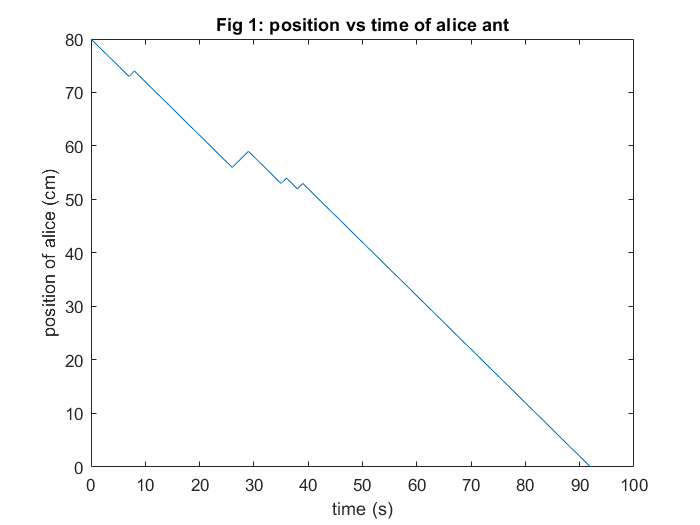

alice_time = 0:1:t;
plot(alice_time,alice_pos)
xlabel('time (s)'),ylabel('position of alice (cm)')
title('Fig 1: position vs time of alice ant')